## Dynamical analysis

We plan to extend the definition provided for kinematic analysis for data required by dynamical analysis (inertias and forces).

Next we will form equations of motion for the system of unconstrained bodies.

Finally we will solve the general multibody equations of motion.

for mass and inertias I used table below.

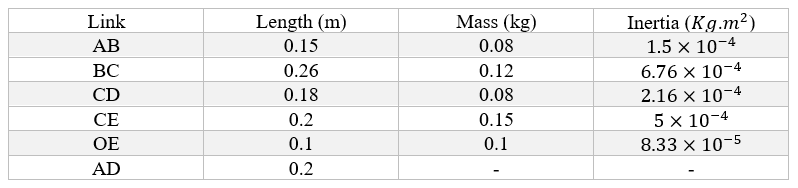

Bodies, inertias, and coordinates

clc;clear;close all;
mbs = init_mbs();
%mbs = add_body(mbs, "ground", 0, 0, 0);
%mbs = add_body(mbs, "ground_D", 0.15, 0.132, 0 );
%mbs = add_body(mbs, "ground_S", 0.15, -0.132, 0 );
mbs = add_body(mbs, "AB", -0.1, 0.1, -deg2rad(30), 'm', 0.08, 'Ic', 1.5e-04);
mbs = add_body(mbs, "BC", -0.15, 0.12, deg2rad(20), 'm', 0.12, 'Ic', 6.76e-04);
mbs = add_body(mbs, "CD", -0.12, 0.1, deg2rad(15), 'm', 0.08, 'Ic', 2.16e-04);
mbs = add_body(mbs, "CE", -0.25, 0.11, deg2rad(25), 'm', 0.15, 'Ic', 5e-04);
mbs = add_body(mbs, "OE", -0.6, 'm', 0.1, 'Ic', 8.33e-5 )

mbs = struct with fields:
     bodies: [1×5 struct]
     joints: [1×1 struct]
         nq: 15
         nc: 0
    gravity: []
     forces: [1×1 struct]
     balpha: 5
      bbeta: 5


Get mass matrix

M = mass_matrix(mbs)

M =     0.0800         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0800         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.0001         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0    0.1200         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0    0.1200         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0    0.0007         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0    0.0800         0         0

### Forces definition

mbs = add_gravity(mbs, [0, -9.81]);

### Force vector

q0 = initial_position(mbs);
F = forces(mbs, q0)

F =          0
   -0.7848
         0
         0
   -1.1772
         0
         0
   -0.7848
         0
         0


Simple checking for the gravity forces

qpp = M\F

qpp =          0
   -9.8100
         0
         0
   -9.8100
         0
         0
   -9.8100
         0
         0


### Solve system using EulerCromer

Define all the inputs to the system

% [t, U, V] = EulerCromer(accfun, T, U_0, V_0, dt)
accfun = @(u, v, t)acceleration(mbs, u, v, t);
T = 1.0;
qd0 = zeros(size(q0)); % initial velocity
qd0([1, 4, 7, 10]) = -0.08; % Set vx of AB and vx of BC and vx of CD and vx CE
h = 0.01;
[t, Q, Qp] = EulerCromer(accfun, T, q0, qd0, h);


Make some plots to check the results

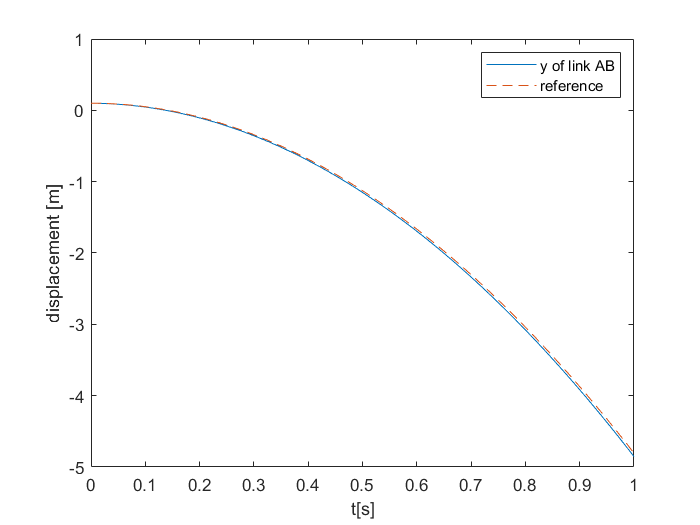

plot(t, Q(:, 2), t, q0(2) + t.*qd0(2) - 9.81 * 0.5 .* t .^ 2, '--')
legend('y of link AB', 'reference')
xlabel('t[s]')
ylabel('displacement [m]')

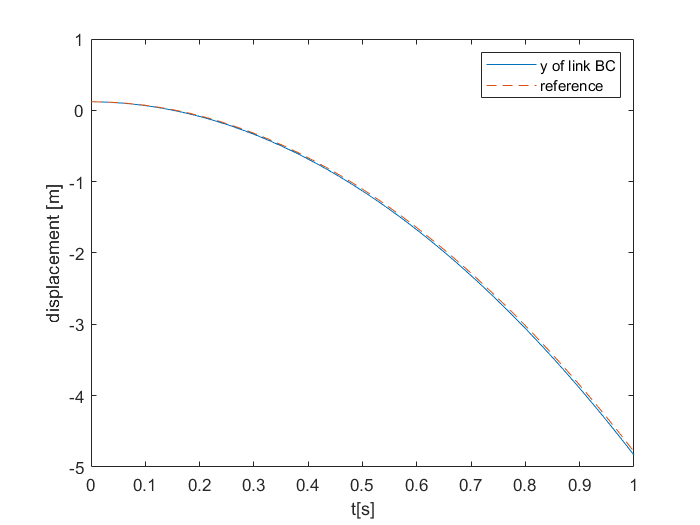

plot(t, Q(:, 5), t, q0(5) + t.*qd0(5) - 9.81 * 0.5 .* t .^ 2, '--')
legend('y of link BC', 'reference')
xlabel('t[s]')
ylabel('displacement [m]')

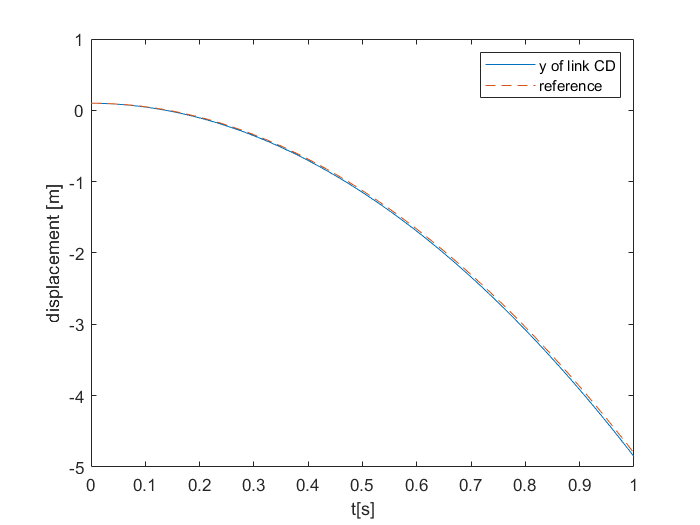

plot(t, Q(:, 8), t, q0(8) + t.*qd0(8) - 9.81 * 0.5 .* t .^ 2, '--')
legend('y of link CD', 'reference')
xlabel('t[s]')
ylabel('displacement [m]')

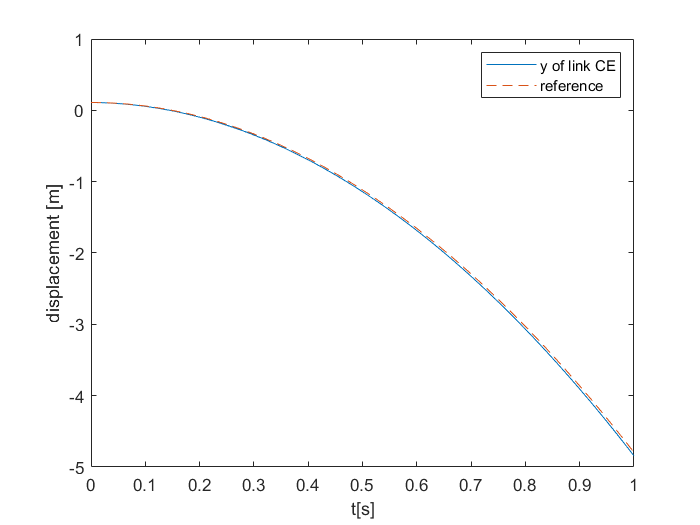

plot(t, Q(:, 11), t, q0(11) + t.*qd0(11) - 9.81 * 0.5 .* t .^ 2, '--')
legend('y of link CE', 'reference')
xlabel('t[s]')
ylabel('displacement [m]')